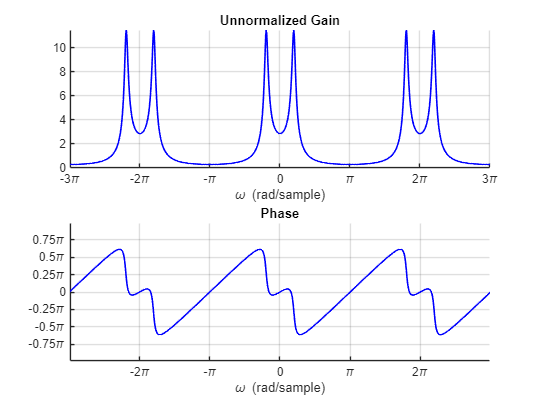

w = linspace(-3*pi, 3*pi, 1001);
% from y[n] = 1.5y[n-1] - 0.85y[n-2] + x[]
%b = 1;
%a = [1 -1.5 0.85];
%H = freqz(b, a, w);  
H = 1 ./ (1 - 1.5*exp(-1i*w) + 0.85*exp(-1i*2*w));

figure(1)
% Magnitude
A = subplot(2,1,1);
line(w, abs(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Unnormalized Gain')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})

subplot(2,1,2)
xlim([-9.4 9.4])
ylim([-3.1 3.1])

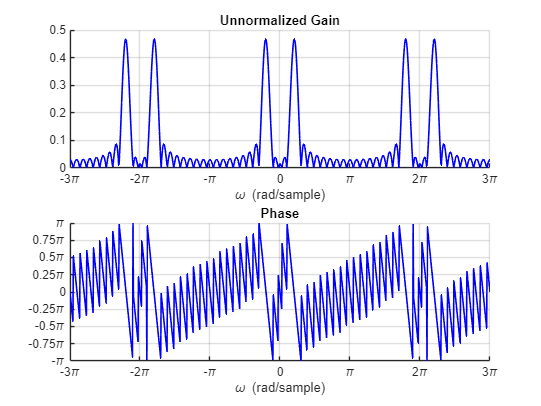



load("FIR.mat");
H = 0;
for n = 1:length(hn)
    H = H + hn(n) * exp(-1i*w*(n-1));
end

figure(2)
% Magnitude 
A = subplot(2,1,1);
line(w, abs(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)]);
xlabel('\omega (rad/sample)')
title('Unnormalized Gain')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})

% Phase
A = subplot(2,1,2);
line(w, angle(H), 'Color', 'b', 'LineWidth', 1.2);
set(A, 'XLim', [w(1) w(end)], 'YLim', [-pi pi]);
xlabel('\omega (rad/sample)')
title('Phase')
grid on
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
yticks([-pi -0.75*pi -0.5*pi -0.25*pi 0 0.25*pi 0.5*pi 0.75*pi pi])
yticklabels({'-\pi','-0.75\pi','-0.5\pi','-0.25\pi','0','0.25\pi','0.5\pi','0.75\pi','\pi'})